## Define Problem Parameters

% Define data for each items
weights = [5, 1, 9, 9, 6, 5, 2, 5, 6, 7];
volumes = [12, 12, 17, 14, 15, 12, 19, 12, 20, 13];
values = [62.30, 32.53, 59.38, 65.12, 48.67, 14.36, 69.52, 84.71, 6.58, 46.99];
nItems = length(weights);

% Define three constraints
maxWeightLimit = 30;
maxVolumeLimit = 50;
maxItemsSelected = 5;

% Items selection with all integers
lb = zeros(nItems, 1);
ub = ones(nItems, 1);
intCon = 1:nItems;



Single objective optimization:
10 Variables
10 Integer variables
3 Nonlinear inequality constraints

Options:
CreationFcn:       @gacreationuniformint
CrossoverFcn:      @crossoverlaplace
SelectionFcn:      @selectiontournament
MutationFcn:       @mutationpower

                                  Best          Mean         Stall
Generation      Func-count     Penalty         Penalty    Generations
    1              198          -219.3          -87.28        0
    2              293          -219.3           -48.2        1    3              388          -226.5          -95.82        0
    4              483          -226.5          -44.85        1    5              578          -226.5          -85.65        2
    6              673          -244.7          -31.94        0    7              768          -244.7          -82.65        1
    8              863          -244.7          -76.83        2    9              958          -244.7          -65.93        3
   10             1053     

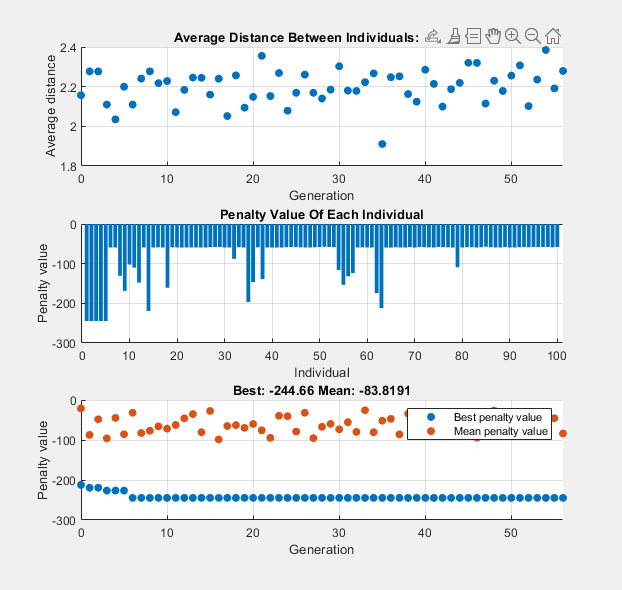

% Pass fixed parameters to objfun
objfun3 = @(x)knapsackObjective(x,values,weights,volumes,maxWeightLimit,...
    maxVolumeLimit,maxItemsSelected);

% Pass fixed parameters to confun
confun3 = @(x)knapsackConstraints(x,weights,volumes,maxWeightLimit,...
    maxVolumeLimit,maxItemsSelected);

% Set nondefault solver options
options2 = optimoptions("ga","CrossoverFraction",0,"PopulationSize",100,...
    "ConstraintTolerance",1e-06,"Display","iter","PlotFcn",["gaplotdistance",...
    "gaplotscores","gaplotbestf"]);

% Solve
[solution,objectiveValue] = ga(objfun3,nItems,[],[],[],[],lb,ub,confun3,intCon,...
    options2);


% Clear variables
clearvars objfun3 confun3 options2


disp(solution)

     1     1     0     1     0     0     0     1     0     0



disp(objectiveValue)

 -244.6600



## Local Function 

### (Objective Function)

function totalValue = knapsackObjective(x, values, weights, volumes, maxWeight, maxVolume, maxItems)
    % Ensure x is a binary vector
    x = round(x);
    
    % Calculate the total weight, total volume, and total value of the selected items
    % totalWeight = sum(weights .* x);
    % totalVolume = sum(volumes .* x);
    totalValue = -sum(values .* x);
    
    % % Penalize solutions that exceed the maximum weight or volume or items
    % if totalWeight > maxWeight
    %     totalValue = totalValue - 1000 * (totalWeight - maxWeight);
    % end
    % if totalVolume > maxVolume
    %     totalValue = totalValue - 1000 * (totalVolume - maxVolume);
    % end
    % if sum(x) > maxItems
    %     totalValue = totalValue - 1000 * (sum(x) - maxItems);
    % end
end


### (Constraint Function)

function [c, ceq] = knapsackConstraints(x, weights, volumes, maxWeight, maxVolume, maxItems)
    % Ensure x is a binary vector
    x = round(x);

    % Calculate the total weight, volume, and number of selected items
    totalWeight = sum(weights .* x);
    totalVolume = sum(volumes .* x);
    totalItems = sum(x);

    % Define the inequality constraints
    c = [totalWeight - maxWeight; % Total weight must be less than maxWeight
         totalVolume - maxVolume; % Total volume must be less than maxVolume
         totalItems - maxItems];  % Number of items must be less than maxItems

    % No equality constraints
    ceq = [];
end
